# NSCS 344, Week 3

# Response times

## A modified version of the dots task

This week we will modify a slightly different version of the dots task in which we can model the response time in addition to the choice.  

In this version of the task, participants see a continuous stimulus of dots that does not stop until they indicate their choice. Thus, participants have the option to keep gathering information until they are sure which way the dots are going. 

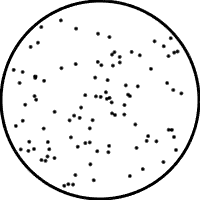

In this task we don't just model the choice, but also how quickly that choice is made. Participants (often implicitly, but sometimes explicitly) are under pressure to respond quickly (if you've ever taken part in a perceptual psychology experiment you will understand the desire to just "get out of there as quickly as possible!"). However, responding quickly leads to more chance of making a mistake and participants need to manage a tradeoff between being fast and being correct known as the ***speed-accuracy tradeoff.***

We will see this week how a slight tweak to our simple counting model can model response times in the dots task and account for the speed accuracy tradeoff.  

In addition, we will also see how this simple averaging model appears to correlate with the firing rates of neurons of monkeys performing this task, suggesting that our "simple" model may actually be implemented in the brain.

## A modified version of the model

To model response times in the dots task we need to do four things.

- Compute N_correct and N_wrong on each frame of the movie

- Compute the difference, $\Delta$ between N_correct and N_wrong on each frame of the movie

- Integrate the difference over time

- Make a decision when the integrated difference crosses some threshold.

## Computing N_correct and N_wrong on each frame

we will first reframe our existing model in a slightly different way. Remember how our model worked? We had a direction for each dot (correct direction or wrong direction) and then summed up all the dots moving in the correct direction and wrong direction and made our decision accordingly. 

In the makeOneDecision function, this was implemented in Matlab as

Today we are going to reframe this slightly to compute the number of dots moving in the correct direction and the wrong direction *on every frame of the movie. *

Let's do this in a script first so we can see what's going on and plot things a little easier.  First, let's setup the variables we want for this decision

clear

% number of dots
D = 10;

% number of movie frames
T = 20;

% fraction of dots moving in correct direction
f = 0.55;

Then, instead of one loop over $D\times T$ dots let's put in *two *loops over all the dots in each frame and all the frames in each movie like this ...

for i = 1:T
    
    % initialize count variables
    N_correct = 0;
    N_wrong = 0;
    
    for j = 1:D
        % randomly sample the direction of this dot
        dot_direction = binornd(1, f);
        
        % update the counts
        N_correct = N_correct + dot_direction;
        N_wrong = N_wrong + (1 - dot_direction);
        
    end
end

Note that I'm initializing the count to zero at the start of each loop, so I get a separate count for correct and wrong for each loop.

However, I've missed something in this code.  Can you see what it is?

I'm not *storing* the number moving in the correct and wrong direction for each frame of the movie.  A simple way to do this is to add an (i) index to N_correct and N_wrong like this

for i = 1:T
    
    % initialize count variables
    N_correct(i) = 0;
    N_wrong(i) = 0;
    
    for j = 1:D
        % randomly sample the direction of this dot
        dot_direction = binornd(1, f);
        
        % update the counts
        N_correct(i) = N_correct(i) + dot_direction;
        N_wrong(i) = N_wrong(i) + (1 - dot_direction);
        
    end
end
N_correct

N_correct =      6     8     6     6     5     6     5     4     4     4     7     5     6     7     6     3     6     5     6     6


N_wrong

N_wrong =      4     2     4     4     5     4     5     6     6     6     3     5     4     3     4     7     4     5     4     4


Note that note, N_correct and N_wrong and vectors of length 20 corresponding to the count of dots moving in the correct and wrong direction on each frame of the movie.

## Compute the difference

Next we need to take the difference between N_correct and N_wrong on each frame of the movie.  To do this we can just add a line to the for loop over T ...

for i = 1:T
    
    % initialize count variables
    N_correct(i) = 0;
    N_wrong(i) = 0;
    
    for j = 1:D
        % randomly sample the direction of this dot
        dot_direction = binornd(1, f);
        
        % update the counts
        N_correct(i) = N_correct(i) + dot_direction;
        N_wrong(i) = N_wrong(i) + (1 - dot_direction);
        
    end
    
    % compute the difference
    Delta(i) = N_correct(i) - N_wrong(i);
end

and this will definitely work. 

## Integrate the difference

Next we need to compute the 